# Stability Analysis of Dynamical Systems 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state space model. 

Analysing the stability properties of a dynamical system is a core problem in control theory, as it rigorously characterises when a system is "*well-behaved*" or not. This file introduces some of the basic tools used to determine stability of state-space systems.    As ever, use text books for more detail on the theoretical aspects.

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by Ross Drummond with some input from Anthony Rossiter, Lanlan Su (University of Sheffield) and Ruth Bars ( Budapest University of Technology and Economics)  

                         

## Table of Contents

- Stability of linear time invariant systems

- Eigenvalues and eigenvectors of matrices

- Computing eigenvalues and eigenvectors

- Diagonalisation of system dynamics

- Stability theorems

- Local asympotic stability of nonlinear systems

- Conclusions

## 1. Stability of linear time invariant systems

In this code, the problem of determining the stability properties of a closed linear time-invariant state-space (LTI) system is explored. We will focus on closed LTI systems with dynamics

                                                                                                                            
$$\frac{dx(t)}{dt} = Ax(t), \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad  \qquad \qquad \qquad \qquad \qquad \qquad  \text{Eqn. } (1)$$


where $A \in \mathbb{R}^{n\times n$ is a matrix and $x(t)\in \mathbb{R}^n$ is the system's state evolving in time. The state could be any variable of interest in the system, for example it could be a vehicle's acceleration or the charge in battery. As we will see, the stability properties of LTI systems are characterised the *eigenvalues* of the matrix $A$. In fact, it is through computing the eigenvalues of this matrix that the full stability properties of this system are revealed. To make the analysis self-contained, we will first give a brief summary of what eigenvalues and their corresponding eigenvectors, are for matrices. 

## 2. Eigenvalues and eigenvectors of matrices

This section gives a quick recap about eigenvalues and eigenvectors for matrices. These two tools are at the heart of the broad mathematical field known as "*Linear Algebra*" for which much more detailed  results can be found elsewhere, *e.g.* in Strang, Gilbert. *Introduction to linear algebra*. Wellesley-Cambridge Press, 2022.

### 2.1 Eigenvalue and eigenvectors

The basic idea is that when an** eigenvector**, $v\in \mathbb{R}^n$, is multiplied by the matrix $A\in \mathbb{R}^{n \times n}$, it does not "*rotate*"; instead it only scales by a factor $\lambda$, with $\lambda$ known as an **eigenvalue**. In other words, the following equation is satisfied by the eigenvectors and eigenvalues of a matrix $A$:

                                                                                                                                 
$$Av = \lambda v. \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad  \qquad \qquad \qquad \qquad \qquad \qquad  \text{Eqn. } (2)$$
 

When we said the eigenvector does not "*rotate*", what we mean is that multiplying $v$ by $A$ just scales it by $\lambda$. Note that $\lambda$ can be a real or a complex number. 

#### 2.1.1 Examples

For example, consider the matrix: 

$A= \left[\matrix{2 & 1 \cr 1 & 2}\right]$.

Using the method described in Section 2.3, it can be shown that this matrix has two eigenvalues, and correspondingly two eigenvectors, given by


$$v_1 = \left[\matrix{1 \cr 1}\right], \quad \lambda_1 = 3, \qquad v_2 = \left[\matrix{1 \cr -1}\right], \quad \lambda_1 = 1.$$


These two eigenvectors are shown below.

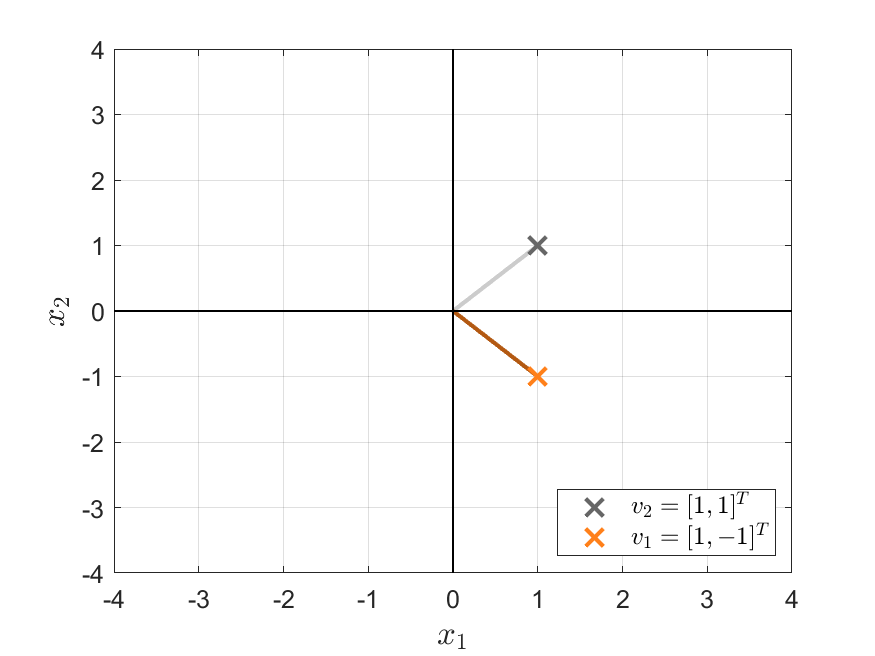

Now, when we multiply these two vectors by the matrix $A$, we get:


$$Av_1 = \left[\matrix{2 & 1 \cr 1 & 2}\right]\left[\matrix{1 \cr 1}\right] = 3 \left[\matrix{1 \cr 1}\right] = \lambda_1 v_1,
\qquad Av_2 = \left[\matrix{2 & 1 \cr 1 & 2}\right]\left[\matrix{1 \cr -1}\right] =  \left[\matrix{1 \cr -1}\right] = \lambda_2 v_2.$$


In otherwords, the eigenvectors have been scaled by the eigenvalues, as in:

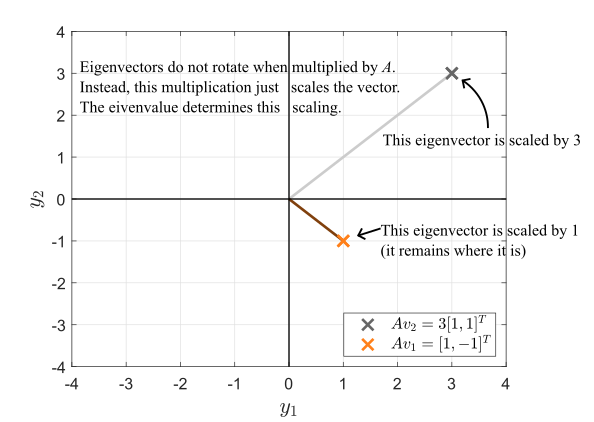

However, notice that this scaling does not hold for all vectors multiplied by the matrices $A$. For example, if we take two other vectors such as: 


$$w_1 = \left[\matrix{-1.2 \cr 2}\right], \quad w_2 = \left[\matrix{-0.5 \cr -1.5}\right]$$


and multiply them by $A$, we get: 

$Aw_1 = \left[\matrix{-0.4 \cr 2.8}\right], \quad Aw_2 = \left[\matrix{-2.5 \cr -3.5}\right]$.

The vectors have been rotated, as can be seen from the following figure:

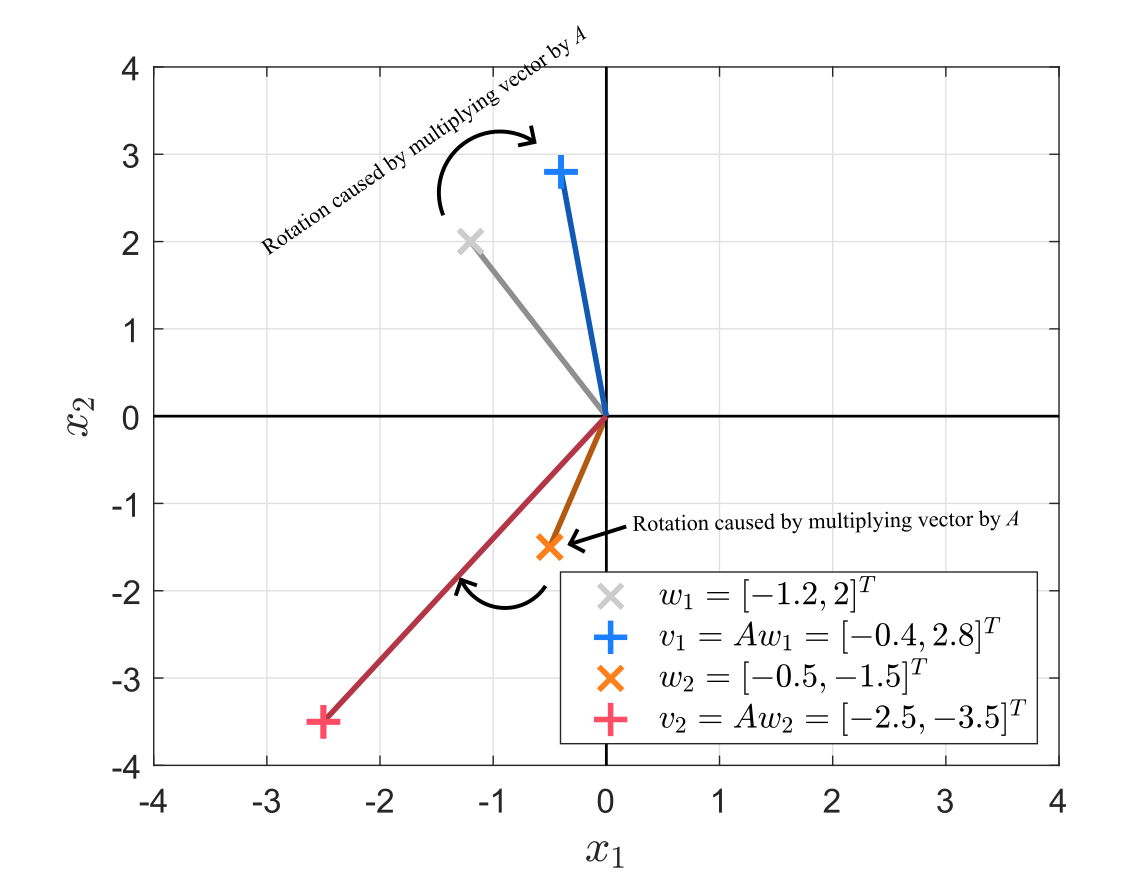

It is this lack of rotation which is key to eigenvectors/eigenvalues and which makes them so useful for our stability analysis problems. 

### 2.2. Eigen decompositions of matrices

We will now use these eigenvalues/eigenvectors as tools to prove stability properties of LTI systems. For this, the main goal is to show that eigenvalues and eigenvectors can be used to transform generic matrices into diagonal ones.  For a $n \times n$ matrix $A\in \mathbb{R}^{n \times n}$, we say it is **diagonalisable **if there are $n$ solution to Eqn. (2), as in if $n$ eigenvalues of the form $\lambda_1,,\lambda_2,\, \dots, \,\lambda_n$ and, correspondingly, $n$ eigenvectors  $v_1,,v_2,\, \dots, \,v_n$. Thankfully, *most *matrices of LTI dynamical systems encountered in practice are are diagonalisable (which makes the analysis easier). But, there are specific cases (*e.g.* nilpotent matrices) which are not. We will explore this special case in Section 3 on the matrix Jordan form. But, for now, we focus our analysis on diagonalisable matrices as those define most common LTI systems found in practice. 

If our matrix is diagonalisable, then we can then collect the eigenvalues,$\lambda_1,,\lambda_2,\, \dots, \,\lambda_n$, together and form a matrix $\Lambda$ of the form:

$\Lambda = \left[\matrix{\lambda_1 & 0 & \dots & 0  \cr 0  &\lambda_2 & \ddots & \vdots \cr
\vdots & \ddots & \ddots & 0 \cr
0 & \dots & 0 & \lambda_n}\right]$.

 Similarly, we can also stack the $n$ eignevectors, $v_1,,v_2,\, \dots, \,v_n$, into another matrix:

$V = [v_1,\,v_2, \dots,\, v_n]$.

Using the matrix of eigenvalues, $\Lambda$, and eigenvectors, $V$, we can now write out a matrix form of Eqn. (2), as in:

$AV = \Lambda V$.

For our purposes of proving the stability of LTI systems, the key property that we can exploit from this relationship between $A, \,V$ and $\Lambda$ is that it implies that we can express our original matrix$A$ as: 

$A = V\Lambda V^{-1}$.

In this case, we say that the matrix $A$ is **similar** to $\Lambda$. As $A$ is similar to a diagonal matrix $\Lambda$, we say it is **diagonalisable** (as in, there exists some transformation $V$ such that $A$ can be converted into a diagonal matrix). What this representation implies is that if we multiply $A$ on the left by the matrix of eigenvectors, $V$, and on the right by its inverse, $V^{-1}$, then we will get a diagonal matrix formed from the eigenvalues $\Lambda$, as in:

$\Lambda = V^{-1} AV$.

This is known as the **eigendecomposition **of the matrix $A$ and is the basic trick that allows to analyse the stability of LTI systems. This is because it allows us to convert a problem involving $n \times n$ matrices into $n$ decoupled problems, which is significantly earier to analyse. The code here illustrates the process numerically (the error is due to the limits of computational accuracy).

A= rand(n);
[V,D] = eig(A);
Lambda = V\A*V;
error = norm(D-Lambda)

error = 1.0320e-15

disp('The difference between the matrix of eigenvalues and $V^{-1}AV$ is:');

The difference between the matrix of eigenvalues and $V^{-1}AV$ is:


disp(error);

   1.0320e-15



## 2.3 Computing eigenvalues and eigenvectors

But how can the eigenvalues, $\lambda_k$, and, and eigenvalues $v_k$ for $k = 1,2,\dots,\,n$ actually be computed? That is the problem considered in this section.

 We start by computing the eigenvalues.  To do this, re-write the eigenvalue equation as


$$(A-\lambda_k)v_k = 0, \qquad \text{for all } k = 1,\,\dots,, n.$$


It can be shown, *e.g.* in Strang, Gilbert. *Introduction to linear algebra*. Wellesley-Cambridge Press, 2022, that the above equation has a solution if, and only if, 

$\text{det}(A-\lambda_kI_n) = 0$,

where $\text{det}(A-\lambda_kI_n)$ refers to the determinant of the matrix $A-\lambda_kI_n$. The above equation allows us to to link the determinant of a matrix to its eigenvalues, and as such, it provides a constructive way to compute them. 

Specifically, from the* fundamental theorem of algebra* [Strang, Gilbert. *Introduction to linear algebra]*, it can be shown that for some arbitrary number $\lambda$, that:

$\text{det}(A-\lambda I_n) = (\lambda-\lambda_1) \times  (\lambda-\lambda_2) \times \dots \times  (\lambda-\lambda_n) =0$,

where, again, $\lambda_k$ are the eigenavlues of $A$. As an aside, it is noted that the above equation is independent of the sign of $A-\lambda I_n$, since 


$$\text{det}(\lambda-A) = \text{det}(A-\lambda) = (\lambda-\lambda_1) \times  (\lambda-\lambda_2) \times \dots \times  (\lambda-\lambda_n) =0.$$


The equation $\text{det}(\lambda-A) =0$ is a polynomial equation and the above result shows that the roots of that polynomial equation, $\lambda_k$, are eigenvalues of $A$. 

#### Example: 

For example, consider the matrix

$A= \left[\matrix{2 & 1 \cr 1 & 2}\right]$.

The eigenvalue equation is


$$\text{det}\left(\lambda I_2-A\right)
=\text{det}\left(\left[\matrix{\lambda & 0 \cr 0 & \lambda}\right]-\left[\matrix{2 & 1 \cr 1 & 2}\right]\right)
=\text{det}\left(\left[\matrix{\lambda-2 & -1 \cr -1 & \lambda-2}\right]\right)
= (\lambda-2)^2-1
= \lambda^2-4\lambda+3
=(\lambda-3)(\lambda-1) = 0.$$


The eigenvalues of this matrix are then $\lambda_1 = 1$and $\lambda_2 = 3$. Alternatively, one could solve this numerically.

A= [2 1 ;1 2];
eigs= eig(A);
disp('The eigenvalues of the matrix are:');

The eigenvalues of the matrix are:


disp(eigs);

     1
     3



#### 2.3 Calculating matrix determinants

A quick reminder on determinants for matrices. The determinnat of a matrix roughly characterises its "*volume*"  and is a crucial operation for many mathematical analysis problems.  For $2\times 2$ matrices, of the form:


$$A= \left[\matrix{a & b \cr c & d}\right]$$


the deteminant is calculated by


$$\text{det}(A)= ad-bc.$$


For example


$$\text{det}\left( \left[\matrix{1 & 2 \cr 3 & 4}\right]\right) = 1 \times 4- 2 \times3 = -2.$$


A= [1 2; 3 4];
det_A= det(A);
disp('The determinant of the matrix is:');

The determinant of the matrix is:


disp(det_A);

    -2



For larger matrices, the determinant is harder to compute. With $3\times 3$ matrices of the form:


$$A= \left[\matrix{a & b  & c\cr d & e & f \cr g & h & i}\right]$$
 

the equation is more complicated

$\text{det}(A) = a\times \text{det}\left(\left[\matrix{e& f \cr h & i}\right]\right)-b \times \text{det}\left(\left[\matrix{d& f\cr g & h}\right]\right)+c \times \text{det} \left(\left[\matrix{d& e \cr g & h}\right]\right)$.

 For example,


$$\text{det}\left( \left[\matrix{0 & 1 & 0\cr 2 & 3 & 4 \cr 5 & 6 & 7}\right]\right) 
=
0\times \text{det}\left(\left[\matrix{3& 4 \cr 6 & 7}\right]\right)-1 \times \text{det}\left(\left[\matrix{2& 4\cr 5 & 7}\right]\right)+0 \times \text{det} \left(\left[\matrix{2& 3 \cr 5 & 6}\right]\right)
=
-(2\times 7-4 \times 5) = 6.$$


A= [0 1 0; 2 3 4; 5 6 7];
det_A= det(A);
disp('The determinant of the matrix is:');

The determinant of the matrix is:


disp(det_A);

    6.0000



The complexity of computing determinants generally scales  with the dimension of the matrix, and so we generally use computers for these tasks. A general rule is, typically, only compute determinants by hand for matrices of size $2 \times 2$ matrices or less. Otherwise the algebra gets too unwieldy unless a mathematic trick can be used which exploits the structure of the matrices. 

#### 2.3 Further notes on matrix determinants

As a side note, we refer to two other properties of matrices which are useful when checking whether the computed eigenvalues make sense or not. 

**Condition1:** The determinant of a matrix equals the product of its eigenvalues

$\text{det}(A) = \prod_{k =1 }^n\lambda_k = \lambda_1\times \lambda_2 \times \dots \times \lambda_n$.

**Condition 2: **The trace of a matrix equals the sum of its eigenvalues


$$\text{trace}(A) = \sum_{k =1 }^n\lambda_k = \lambda_1+ \lambda_2 +  \dots +  \lambda_n$$


where the trace operation defines the sum of the diagonal elements of a matric, as in


$$\text{trace}(A) = \text{trace}\left(
\left[\matrix{a_{1,1} & a_{1,2}  & \dots & a_{1,n} \cr a_{2,1} & a_{2,2}  & \ddots & \vdots
\cr
\vdots & \ddots& \ddots & a_{n-1,n}  
\cr a_{n,1}    & \dots & a_{n,n-1} & a_{n,n} }\right]\right) = a_{1,1}+a_{2,2}+\dots +a_{nn}.$$


Returning to our example of $\left[\matrix{2 & 1 \cr 1 & 2}\right]$with eigenvalues at $\lambda_1 = 3$ and $\lambda_2 = 1$, we can verify that:


$$\text{det}\left(\left[\matrix{2 & 1 \cr 1 & 2}\right]\right) = 2\times 2-1\times 1 = 3 = 1 \times 3 = \lambda_1 \times \lambda_2,$$


and, furthermore, that:


$$\text{trace}\left(\left[\matrix{2 & 1 \cr 1 & 2}\right]\right) = 2+2 = 1 + 3 = \lambda_1 +\lambda_2.$$


These tricks are often useful for checking whether the eigenavlues of a matrix we have computed make sense. For example, imagine you know a matrix $P$ of the form:


$$P = \left[\matrix{p_{1} & p_{2} \cr p_{2} & p_3}\right]$$


is positive-definite (as in both its eigenvalues are positive). This is a key property of matrices for control as it relates to the energy of the system. Now, since the determinant of the matrix is the product of its eigenvalues, the determinant of $P$ must be positive and so it must satisfy:


$$\text{det}(P) =p_1\times p_3 -p_2^2 = \lambda_1\times \lambda_2 >0.$$


This trick gives an easy-to-compute check for whether the $P$ matrix you have computed is positive-defintie or not. This can be useful for verifying the solution of LQR control problems. 

Another trick is the fact that **complex eigenvalues always come in pairs. **What this means is that if the eigenvalue is a complex number of the form $\lambda_k = a+b i$, then there exists a second one of the form $\lambda_j = a-bi$. Again, this is another trick which can help catch silly mistakes in the algebra when computing eigenvalues. 

A final trick is to note that the eigenvalues of symmetric matrices are always real. Symmetric matrices satisfy $A = A^T$, as they equal there own transpose. For example, consider the following symmetric matrices which all have real eigenvalues. 

A= [1 2 3; 2 4 5; 3 5 6];
B= [4 -1 -5; -1 4 5; -5 10 6];
C= A';
D = B';
E = A-A';

disp('The eigenvalues of A are:');disp(eig(A));

The eigenvalues of A are:
   -0.5157
    0.1709
   11.3448



disp('The eigenvalues of B are:'); disp(eig(B));

The eigenvalues of B are:
   14.1747
    3.0000
   -3.1747



disp('The eigenvalues of C are:'); disp(eig(C));

The eigenvalues of C are:
   -0.5157
    0.1709
   11.3448



disp('The eigenvalues of D are:'); disp(eig(D));

The eigenvalues of D are:
   14.1747
    3.0000
   -3.1747



disp('The eigenvalues of E are:'); disp(eig(E));

The eigenvalues of E are:
     0
     0
     0



By contrast, the opposite property holds for skew-symmetric matrices whose transpose is their negative, as in $A = -A^T$, as  skew-symmetric matrices have purely imaginary eigenvalues. Again, this can be another check to see if the eigenvalues you compute make sense or not (as in, if you have a skew-symmetric matrix and calculate it has real eigenvalues, then the calculations must be incorrect). Here is some code that checks this property for some skew-symmetric matrices. 

A= rand(n);
B= rand(n);
C= rand(n);
D = rand(n);

AA = 0.5*(A-A'); BB =   0.5*(B-B');  CC = 0.5*(C-C');  DD = 0.5*(D-D'); 

disp('The eigenvalues of AA are:');disp(eig(AA));

The eigenvalues of AA are:
   0.0000 + 0.2873i
   0.0000 - 0.2873i
   0.0000 + 0.0000i



disp('The eigenvalues of BB are:'); disp(eig(BB));

The eigenvalues of BB are:
   0.0000 + 0.0000i
   0.0000 + 0.3283i
   0.0000 - 0.3283i



disp('The eigenvalues of CC are:'); disp(eig(CC));

The eigenvalues of CC are:
   0.0000 + 0.2153i
   0.0000 - 0.2153i
   0.0000 + 0.0000i



disp('The eigenvalues of DD are:'); disp(eig(DD));

The eigenvalues of DD are:
   0.0000 + 0.0000i
   0.0000 + 0.1891i
   0.0000 - 0.1891i



## 3. Defective matrices

Unfortunately, not all matrices are diagonalisible; these matrices are known as **defective** matrices. For example, consider the matrix:


$$A= \left[\matrix{0 & 1 \cr 0 &  0}\right]$$


which is a **nilpotent** matrix.

**Definition**: A matrix is said to be **nilpotent** if there exists some integer $k$ such that $A^k = 0.$

Using the matrix above, we can show that it is nilpotent when $k = 2$ as:

$A^2 =  \left[\matrix{0 & 1 \cr 0 &  0}\right] \cdot  \left[\matrix{0 & 1 \cr 0 &  0}\right] =  \left[\matrix{0 & 0 \cr 0 &  0}\right]$.

Nilpotent matrices are often not diagonalisable. For example, when we try to sovle  the eigenvalue equation, we get:


$$ \left[\matrix{0 & 1 \cr 0 &  0}\right]  \left[\matrix{v_1 \cr v_2}\right] =   \left[\matrix{v_2\cr 0}\right]$$


which has lost $v_1$. In fact, it turns out that, there does not exist a $V$ such that


$$V^{-1} \left[\matrix{0 & 1 \cr 0 &  0}\right] V = \Lambda$$


where $\Lambda$ is a diagonal matrix, and so it is not diagonalisable. However, in this case there is a workaround known as the Jordan form of a matrix. 

**Definition: **A marix$A$ is in **Jordan form** if it can be written as $A= VJV^{-1}$ where $J$ is a block diagonal matrix structured as


$$J =  \left[\matrix{J_1 &  & \cr & \ddots & \cr & & J_p}\right]$$


and each Jordan block $J_k$ is defined as

$ J_k = \left[\matrix{\lambda_k & 1& \cr & \lambda_k & \ddots & \cr & & \ddots & 1\cr & & & \lambda_k }\right]$.

These Jordan blacks are upper triangular matrices which *look like* the eigenvalue matrix $\Lambda$ but haves *ones* along their upper-off-diagonal elements. 

Thankfully, every matrix (even defective ones) are known to have a Jordan form. For example, the matrix $A= \left[\matrix{0 & 1 \cr 0 &  0}\right]$ is in Jordan form with $\lambda = 0$.

A= [0 1;0 0];
[V,J] = jordan(A)

V =      1     0
     0     1


J =      0     1
     0     0


The advantage of the Jordan form is that it allows us to analyse defective matrices using similar, but more complicated, methods than those used for diagonaliable matrices. We won't go into the details here, as the intention was to highlight that there exists ways to generalise the analysis to systems where $A$ is not diagonalisble. This was just for completeness; we refer interested readers to more technical literature such as Strang, Gilbert. *Introduction to linear algebra*. Wellesley-Cambridge Press, 2022. In the following we will once again focus on systems described by diagonalisable $A$ matrices as those are commonly found in practice and are simpler to analyse.

## 4. Diagonalisation of system dynamics

Using the eigendecomposition of the matrix $A$ which defines the dynamics of LTI systems, we now have the tools to test the stability of these systems. In the previous code "`stability_analysis_control101_tool.mlx`", formal definitions for what we mean by the stability of a system were given and we are now going to provide techniques to check when those properties are satisfied or not.  Whilst that code gave the formal definitions, the informal definitions of stability is to determine whether the state will "blow up" or not. In general, checking this requires solving an $n^{\text{th}}$-order ordinary differential equation. For example, if our state space system has the form

$ \left[\matrix{\frac{dy(t)}{dt} \cr \frac{d^2y(t)}{dt^2} \vdots \cr \vdots \cr \frac{d^ny(t)}{dt^n} }\right]
=
 \left[\matrix{0  & 1 & 0& \dots \cr \vdots & \ddots & \ddots & \ddots \cr  0  & \dots &0 & 1   \cr -a_0 & -a_1 & \dots &-a _{n-1}}\right]
 \left[\matrix{y(t) \cr \frac{dy(t)}{dt} \vdots \cr \vdots \cr \frac{d^{n-1}y(t)}{dt^{n-1}} }\right]$,

then we have to solve an ordinary differential equation of the form

$
\frac{d^ny(t)}{dt^n}+ a_{n-1}\frac{d^{n-1}y(t)}{dt^{n-1}} + \dots a_1 \frac{dy(t)}{dt} + a_0 y(t) = 0$.

This is hard and the values of the coefficients don't really tell us whether the system will blow up or not. For example, consider the case


$$ \left[\matrix{\frac{dy(t)}{dt} \cr \frac{d^2y(t)}{dt^2} \cr  \frac{d^3y(t)}{dt^3} }\right]
=
 \left[\matrix{0  & 1 & 0 \cr 0 & 0& 1\ \cr -a_0 & -a_1 &-a _{2}}\right]
 \left[\matrix{y(t) \cr \frac{dy(t)}{dt}  \cr  \frac{d^{2}y(t)}{dt^{2}} }\right]$$


Here is an example code to simulate such a system. Two systems are considered: a stable system where $a_0 = 1$, $a_1 = 3$, and $a_3 = 3$ and an unstable one where $a_0 = 1 - \sqrt{2}$, $a_1 = 3$, and $a_3 = 3$. Note the effect of the slight change in the parameter $a_0$ causing the system to go unstable.

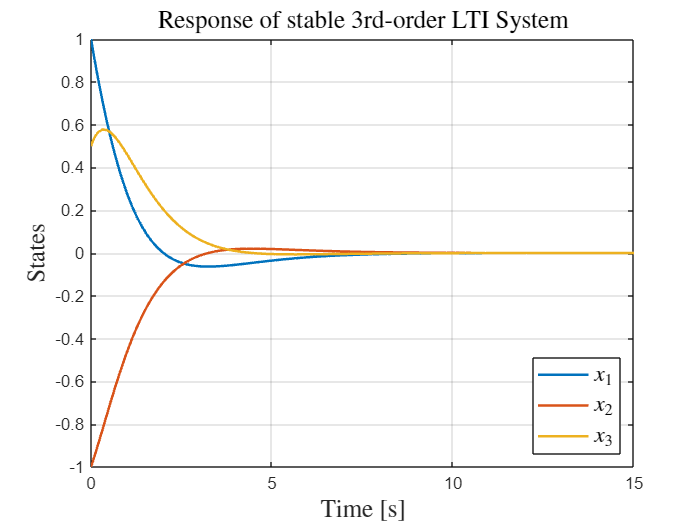

% Define the system matrices (Example 5th-order system)
A = [0 1 0 ;
     0 0 1 ;
     -1 -3 -3]; % Example coefficients

A2 = [0 1 0 ;
     0 0 1 ;
     -1+2^0.5 -3 -3]; % Example coefficients

% Define the initial condition
x0 = [1; -1;  0.5];  % Initial state

% Define the time span for the simulation
tspan = [0 15];  % Simulate from t=0 to t=10


% Define the state-space model as a function for ode45
stateSpaceModel = @(t, x) A*x;
stateSpaceModel_2 = @(t, x) A2*x;

% Solve the system using ode45
[t, x] = ode45(stateSpaceModel, tspan, x0);
[t2, x2] = ode45(stateSpaceModel_2, tspan, x0);

% Plot the results
fig1 = figure;
plot(t, x,'linewidth',1.5);
xlabel('Time [s]' ,'interpreter','latex','fontsize',15);
ylabel('States' ,'interpreter','latex','fontsize',15);
title('Response of stable 3rd-order LTI System','interpreter','latex','fontsize',15);
leg = legend('$x_1$', '$x_2$', '$x_3$');
set(leg,'interpreter','latex','fontsize',14,'location','southeast')
grid on;

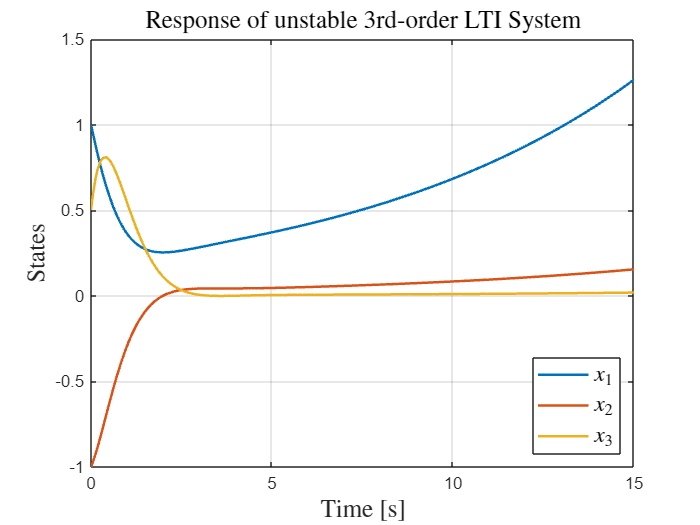


fig2 = figure;
plot(t2, x2,'linewidth',1.5);
xlabel('Time [s]' ,'interpreter','latex','fontsize',15);
ylabel('States' ,'interpreter','latex','fontsize',15);
title('Response of unstable 3rd-order LTI System','interpreter','latex','fontsize',15);
leg = legend('$x_1$', '$x_2$', '$x_3$');
set(leg,'interpreter','latex','fontsize',14,'location','southeast')
grid on;

Even though the stable system looks well behaved, we're not quite sure. To address this ambiguity, let us develop a more mathematical approach to prove stability. 

### Stability analysis using state-transformations

To analyse the stability of an LTI system, we compute the eigendecomposition of the matrix $A$. Specifically, we first propose to use a transformation of our state space $x(t)$.

**Definition: **For a given matrix $V$, a **state-transformation** $\hat{x}(t)$ is defined as $\hat{x}(t) = Vx(t)$. Notive that if $V$ is invertible, then we can recover $x(t)$ from $\hat{x}(t)$ by $x(t) = V^{-1}\hat{x}(t)$.

The key idea of the state-transformation is that it allows us to write our dynamics in terms of a diagonal matrix $\Lambda$. Specifically, we can write the dynamics for transformed state as 

$\frac{d\hat{x}(t)}{dt}  = V\frac{dx(t)}{dt} = VAx(t) = VAV^{-1}Vx(t) = VAx(t) = VAV^{-1}\hat{x}(t)$.

Crucially, we know from the eigendecompostion that $\Lambda = VAV^{-1}$ and is a diagonal matrix whose elements are the eigenvalues of $A$. This implies that we can express the dynamics of our transformed state as: 


$$\frac{d\tilde{x}(t)}{dt} = \Lambda \tilde{x}(t)$$


which can be expanded out as:

$\frac{d}{dt} \left[\matrix{\hat{x}_1(t) \cr \hat{x}_2(t) \cr \vdots \cr \hat{x}_n(t) }\right]
 = \left[\matrix{\lambda_1 & 0 & \dots & 0  \cr 0  &\lambda_2 & \ddots & \vdots \cr
\vdots & \ddots & \ddots & 0 \cr
0 & \dots & 0 & \lambda_n}\right]
 \left[\matrix{\hat{x}_1(t) \cr \hat{x}_2(t) \cr \vdots \cr \hat{x}_n(t) }\right]
=
 \left[\matrix{\lambda_1\hat{x}_1(t) \cr\lambda_2 \hat{x}_2(t) \cr \vdots \cr \lambda_n \hat{x}_n(t) }\right]$.

In other words, the dynamics of our transformed state are now expressed in terms a diagonal matrix. The advanatge of considering this system with the diagonalised matrix is that it decouples each dynamical equation in the model; meaning that the time derivative of $\hat{x}_k(t)$ is only proportional to $\hat{x}_k(t)$ and not dependent upon any other $\hat{x}_j(t)$ where $j \neq k$.

With the state-transformation into the diagonalised system dynamics, the dynamical system under consideration has been converted into $n$ $\times$ first order systems which are significantly easier to analyse. To see this, note that the equations in the transformed vairables are now of the form:


$$\frac{d\hat{x}_k(t)}{dt} = \lambda_k \hat{x}_k(t)$$


where $\lambda_k$ is an eigenvalue of $A$. The solution to this equation is known, and given by:

$\hat{x}_k(t) = e^{\lambda_kt}\hat{x}_k(0)$.

In other words, the growth or decay of the variable $\hat{x}_k(t)$ is directly related to its eigenvalues. Specifically, using the fact that  $e^{a+bi} = e^{a}(\cos(b)+i\sin(b))$ we can expand the solution for $\hat{x}(t)$ out into:


$$\hat{x}_k(t) = e^{\lambda_kt}y_k(0) = e^{a+bi} = e^{Re(\lambda_k)t}(\cos(Im(\lambda_kt)+i\sin(Im(\lambda_kt))\hat{x}(0)$$


where $Re(\lambda_k)$ is the real part of the eigenvalue and $Im(\lambda_k)$ is its negative part. This relation shows that it is the **real part of the eignenvalues** which tells us whether the transformed-state blows up (the part involving the imaginary part of the eignevalue just oscillates). 

Specifically, it shows that:

- If the real part of the eigenvalues of $A$ are positive, then the system blows up expoentially quickly at a rate proportional to $Re(\lambda_k)$.

- If the real part of the eigenvalues of $A$ equal, then the transformed states oscillates at a frequency of $Im(\lambda_k)$.

- If the real part of the eigenvalues of $A$ are strictly negative, then the system decays expoentially quickly at a rate proportional to $Re(\lambda_k)$.

Thus we can link the general shape of the trajectories, and whether they blow up or not, to the eigenvalues of the $A$ matrix, but we are still working in our transformed states. If we want to to go back to our original systems, we just note that:


$$x(t) = V^{-1}\hat{x}(t)$$


and so can map back to our original states. As such, with the modal decompostion into a diagonal form, we can determine the stability from the eigenalues of $A$.

The following code presents this simulation for random systems.

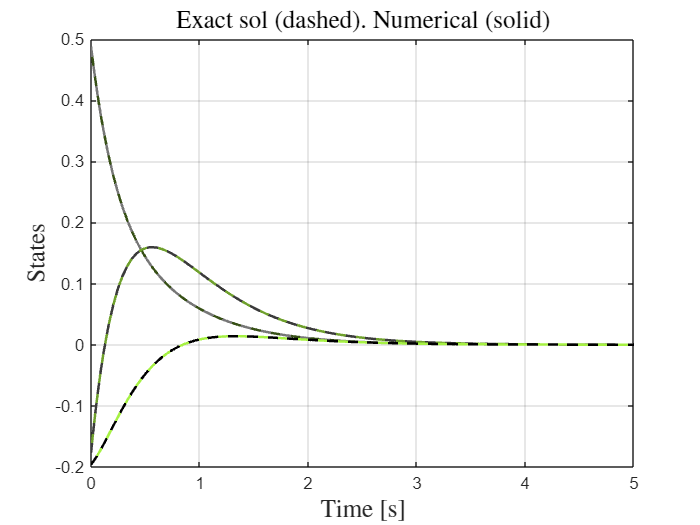

% Define the system matrices (Example 5th-order system)
n = 3;
A = randn(n)-2*eye(n); % Example coefficients

[V,D] = eig(A); % Compute the eigendecomposition.

Adiag = V\A*V; % form the diagonal matrix of the eigenvalues.

% Define the initial condition
x0 = randn(n,1);  % Initial state

% Define the time span for the simulation
tspan = [0 5];  % Simulate from t=0 to t=10


% Define the state-space model as a function for ode45
stateSpaceModel = @(t, x) A*x;

% Solve the system using ode45
[t, x] = ode45(stateSpaceModel, tspan, x0);

x = x';

nt = max(size(t));
lambda = diag(D);
y0 = V\x0;
 y_exact= zeros(n,nt); x_exact = zeros(n,nt);
for j = 1:nt
    y_exact(:,j) = expm(D*t(j))*y0;
    x_exact(:,j) = real(V*y_exact(:,j));
end

color_1 = 1.4*[0.4660 0.6740 0.1880];
color_2 = 0.7*[1 1 1];
% Plot the results
fig1 = figure;
for j = 1:n
plot(t, x(j,:),'color',color_1*j/n,'linewidth',1.5); hold on;
plot(t, x_exact(j,:),'--k','color',color_2*(n-j)/n,'linewidth',1.5); hold on;
end
xlabel('Time [s]' ,'interpreter','latex','fontsize',15);
ylabel('States' ,'interpreter','latex','fontsize',15);
title('Exact sol (dashed). Numerical (solid)','interpreter','latex','fontsize',15);
grid on;

## 5. Stability theorems

Using the results from the previous section connecting the blow-up properties of an LTI system to real parts of the eigenvalues of the matrix $A$, a statement about the stability of this system can now be stated. 

**Theorem 1:** An LTI state-space system is:

- asymptotically stable if and only if all the eigenvalues of $A$ have strictly negative real part.

- unstable if any eigenvalue has a strictly positive real part.

- neutrally stable if the real part of the eigenvalues of A are non-positive, one or more eigenvalue has zero real part, and all eigenvalues with zero real part are simple (i.e.the poles on the imaginary axis are distinct from each other).

With this theorem, we can use the following two steps the check whether a LTI system is stable or not. 

- Compute the eigenvalues of the marix $A$ by solving for the roots of $\text{det}(A-\lambda I_n) = 0$.

- Check whether the real parts of the eigenvalues are strictly negative. If any is not, then is is not asympotically stable. 

To show this in practice, consider again the two systems from Section 4, with: 


$$A =  \left[\matrix{0  & 1 & 0 \cr 0 & 0& 1\ \cr -1 & -3 &-3}\right], 
\qquad A_2 =  \left[\matrix{0  & 1 & 0 \cr 0 & 0& 1\ \cr -1+\sqrt{2} & -3 &-3}\right].$$


Note that we found that the$A$ above defines a stable system whereas $A_2$ has an instability, with one state growing exponentially. We will now examine this stability analysis using the eigenvalues. Computing the eigenvalues of $A$, we get:


$$\text{det}(\lambda I_3-A) = 
\text{det}\left( \left[\matrix{\lambda  & -1 & 0 \cr 0 & \lambda& 1\ \cr 1 & 3 &\lambda +3}\right] \right) 
= \lambda(\lambda\times (\lambda+3))+1 =   \lambda^3+3\lambda^2+3\lambda +1  = (\lambda+1)^3 =0.$$


In other words, all the eigenvalues are at $\lambda = -1$ and so the system is stable as the real part is negative. By contrast, for $A_2$, we have that:


$$\text{det}(\lambda I_3-A_2) = 
\text{det}\left( \left[\matrix{\lambda  & -1 & 0 \cr 0 & \lambda& 1\ \cr 1+\sqrt{2} & 3 &\lambda +3}\right] \right) 
= \lambda(\lambda\times (\lambda+3))+1 =   \lambda^3+3\lambda^2+3\lambda +1+ \sqrt{2}   = (\lambda+1)^3+ \sqrt{2}  =0,$$


which implies that $\lambda = -1+2^{-6}$ . As this is  a positive number, the system is unstable. This is reflected in the following code. 

disp('Section 5 below')

Section 5 below


% Define the system matrices (Example 5th-order system)
A = [0 1 0 ;
     0 0 1 ;
     -1 -3 -3]; % Example coefficients

A2 = [0 1 0 ;
     0 0 1 ;
     -1+2^0.5 -3 -3]; % Example coefficients

eig_A = eig(A);
eig_A2 = eig(A2);

max_eig_A = max(real(eig(A)))

max_eig_A = -1.0000

max_eig_A2 = max(real(eig(A2)))

max_eig_A2 = 0.1225

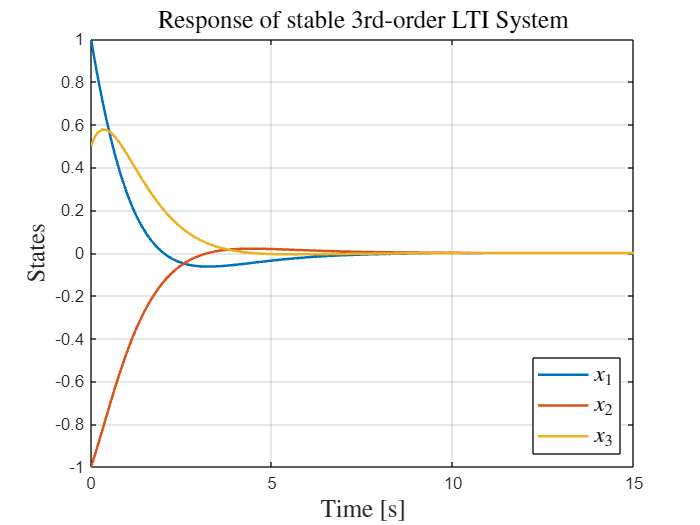


% Define the initial condition
x0 = [1; -1;  0.5];  % Initial state

% Define the time span for the simulation
tspan = [0 15];  % Simulate from t=0 to t=10

% Define the state-space model as a function for ode45
stateSpaceModel = @(t, x) A*x;
stateSpaceModel_2 = @(t, x) A2*x;

% Solve the system using ode45
[t, x] = ode45(stateSpaceModel, tspan, x0);
[t2, x2] = ode45(stateSpaceModel_2, tspan, x0);

% Plot the results
fig1 = figure;
plot(t, x,'linewidth',1.5);
xlabel('Time [s]' ,'interpreter','latex','fontsize',15);
ylabel('States' ,'interpreter','latex','fontsize',15);
title('Response of stable 3rd-order LTI System','interpreter','latex','fontsize',15);
leg = legend('$x_1$', '$x_2$', '$x_3$');
set(leg,'interpreter','latex','fontsize',14,'location','southeast')
grid on;


fig2 = figure;
plot(t2, x2,'linewidth',1.5);
xlabel('Time [s]' ,'interpreter','latex','fontsize',15);
ylabel('States' ,'interpreter','latex','fontsize',15);
title('Response of unstable 3rd-order LTI System','interpreter','latex','fontsize',15);
leg = legend('$x_1$', '$x_2$', '$x_3$');
set(leg,'interpreter','latex','fontsize',14,'location','southeast')
grid on;

## 6. Local asympotic stability of nonlinear systems

The analysis discussed above focussed on state-space systems which are closed and, crucially, linear time invariant. This meant that the state-space dynamics could be defined by a matrix $A$, as in Eqn. (1)  and the powerful tools of linear algebra (e.g. computing eigenvalues and eigenvectors) could then be applied to exactly characterise the stability properties of these LTI systems.

Unfortunately, the world is, in general, not a "linear and time-invariant" system, and is in fact nonlinear. In other words, the world is more complex than the simple models used above. There is then a need to adapt the techniques we discussed above to the nonlinear systems seen in everyday life, and that is what the following section achieves. 

### 6.1 What is a nonlinear system?

To begin, we note that that systems of the form of Eqn (1) are called **linear** because their vector field, a.k.a $dx(t)/dt$, can be expressed as a linear combination of the states through the $Ax(t)$ term. To see this, note that:

$Ax(t) = \left[\matrix{a_{1,1} & a_{1,2}  & \dots & a_{1,n} \cr a_{2,1} & a_{2,2}  & \ddots & \vdots
\cr
\vdots & \ddots& \ddots & a_{n-1,n}  
\cr a_{n,1}    & \dots & a_{n,n-1} & a_{n,n} }\right]
\left[\matrix{x_1(t) \cr x_2(t) \cr \vdots \cr x_n(t)}\right]
=
\left[\matrix{a_{1,1}x_1(t) + a_{1,2}x_2(t)  + \dots & a_{1,n} x_n(t)\cr 
\cr 
a_{2,1}x_1(t) + a_{2,2}x_2(t)  + \dots & a_{2,n} x_n(t)
\cr 
\vdots
\cr 
a_{n,1}x_1(t) + a_{n,2}x_2(t)  + \dots & a_{n,n} x_n(t)}\right]$.

 What is meant by a "**nonlinear system**" is one whose dynamics are described by something more complex than a matrix $A$ multiplied by the state $x(t).$ The vector fields of a nonlinear systems can be composed of any mathematical term that we can think of and so are very general. This generality means that they can describe a whole range of phenomena, but also comes at the cost of making them much harder to simulate and analyse. For  nonlinear models, we typically write them as:


$$\frac{dx(t)}{dt} = F(x(t))$$


where $F(x(t)): \mathbb{R}^n \to \mathbb{R}^n$ could be any nonlinear function. 

#### Examples

For example, the **Van Der Pol Oscillator** is described by:


$$\frac{d}{dt} \left[\matrix{x_1(t) \cr x_2(t)}\right]
 =
\left[\matrix{x_2(t)\cr \mu(1-x_1(t)^2)\times x_2(t)-x_1(t)} \right]$$


 for some parameter value $\mu$. This system is of the form:  


$$F(x(t)) = \left[\matrix{F_1(x(t)) \cr F_2(x(t))} \right]=
\left[\matrix{x_2(t)\cr \mu(1-x_1(t)^2)\times x_2(t)-x_1(t)} \right]$$


and is non-linear because of the polynomial term$ \mu(1-x_1(t)^2)\times x_2(t)
$.  As this term can't be expressed as a linear combination of the states, the dynamics are nonlinear. 

Another example are the dynamics associated with what are are called **Chua circuits:**

$\frac{d}{dt} \left[\matrix{x_1(t) \cr x_2(t) \cr x_3(t) }\right]
 =
\left[\matrix{\alpha (x_2(t) - x_1(t) - (m_1 x_1(t) + \frac{1}{2}  (m_0 - m_1) (|x_1(t) + 1|) - |x_1(t) - 1|) ) \cr
        x_1(t) - x_2(t) + x_3(t) \cr
        -\beta x_2(t)} \right]$.

Here, the nonlinear term is due to the absolute values $|x_1(t) + 1| \text{ and }|x_1(t) - 1|$ since these, again, are not of the form a linear coefficient in front of the states.

Besides such classical nonlinear systems, other nonlinear terms include sinuoids, logarithms, saturations, deadzones, quantisation etc, e.g. where 


$$\frac{d}{dt} \left[\matrix{x_1(t) \cr x_2(t) }\right]
 =
\left[\matrix{\sin(x_2(t))+\ln(1+x_1(t)^2)
\cr
-{x_2}^3+\tanh(x_1)} \right]$$
 

In practice, one often encounters nonlinearities to do with the implementation of a control system in real hardware. For example, the control input $u(t)$ is often saturated, $\text{sat}(u(t))$ meaning that there are limits to the amount of control that can be applied,


$$\text{sat}(u(t)) = \begin{cases}u_{\max} & \text{when }u(t) \geq u_\max ,\\ 
u(t) & \text{when }u_\min  \leq u(t) \leq u_\max , \\
u_{\min} & \text{when }u_\min  \leq u(t).
\end{cases}$$


Examples include the fact that ailerons in aircraft can only rotate a certain amount or when only a finite amount of power can be applied to control the system. The effect of this saturation can be significant, and even destabilise systems that are previously stable. In the code below, an example of a system whose dynamics are significantly affected by saturation is shown, with this example adapted from  Fitts, R. "Two counter examples to Aizerman's conjecture." *IEEE Transactions on Automatic Control* 11.3 (1966): 553-556. using the ideas from Kuznetsov, N. V., et al. "Counterexamples to the Kalman conjectures." *IFAC-PapersOnLine* 51.33 (2018): 138-143.

As the above examples have shown nonlinear systems are much broader than linear ones (they can include any term in the dynamics, not just linear combinations of the states), but also able to express a much richer set of dynamics. In practice, nonlinear systems are found everywhere, from saturation limits, to robot kinematics as it walks over uneven terrain to the electrochemical reactions found in dynamical systems such as lithium-ion batteries and neurons in the brain. They also can generate a richer set of dynamical behvaiour, with properties such as limit cycles, chimera states, chaos and multiple equlibria often found [Strogatz, Steven H. *Nonlinear dynamics and chaos: with applications to physics, biology, chemistry, and engineering*. CRC press, 2018]. This means we have to be careful when analysing nonlinear systems, and whole books/careers/academic fields have been developed to understand them. So, dealing with nonlinear system is unavoidable is we want to try and control and analyse physical systems. 

Here is code to simulate the Van der Pol Oscilator.

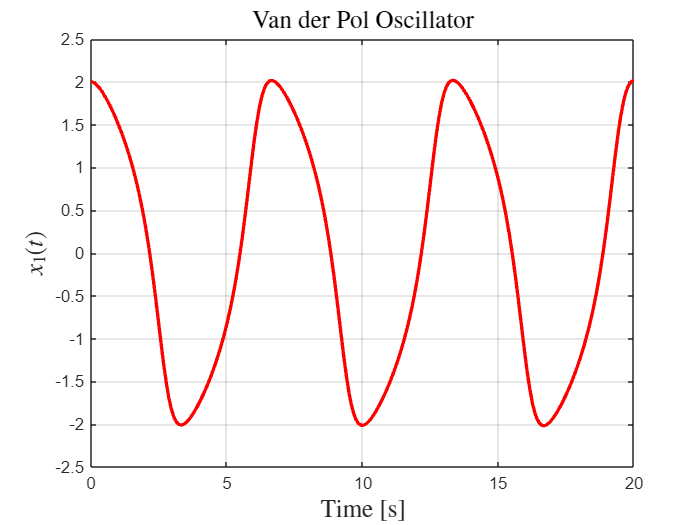

% Parameters
mu = 1;  % Nonlinearity parameter

% Define the system of ODEs for Van der Pol Oscillator
vanderpol = @(t, x) [x(2); mu*(1 - x(1)^2)*x(2) - x(1)];

% Initial conditions
x0 = [2; 0];  % Initial values for [x1; x2]

% Time span
tspan = [0 20];  % Simulate from t=0 to t=20

% Solve the system using ode45
[t, x] = ode45(vanderpol, tspan, x0);

% Plot the results
figure;
plot(t, x(:, 1), 'r', 'LineWidth', 2);
xlabel('Time [s]','interpreter','latex','fontsize',15);
ylabel('$x_1(t)$','interpreter','latex','fontsize',15);
title('Van der Pol Oscillator','interpreter','latex','fontsize',15);
grid on;

Here is code to simulate Chua's circuit.

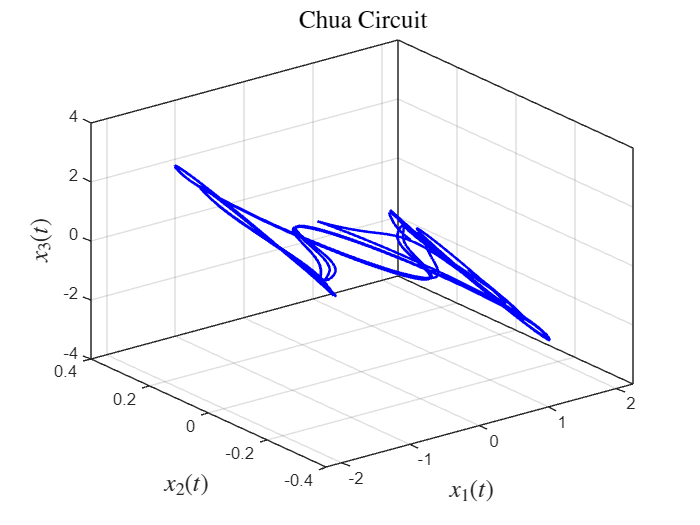

% Parameters for Chua's Circuit
alpha = 9;
beta = 14.286;
m0 = -1.143;
m1 = -0.714;

% Define the piecewise linear function f(x1)
f = @(x1) m1*x1 + 0.5*(m0 - m1)*(abs(x1 + 1) - abs(x1 - 1));

% Define the system of ODEs for Chua's Circuit
chua = @(t, x) [alpha*(x(2) - x(1) - f(x(1)));
                x(1) - x(2) + x(3);
                -beta*x(2)];

% Initial conditions
x0 = [0.7; 0; 0];  % Initial values for [x1; x2; x3]

% Time span
tspan = [0 50];  % Simulate from t=0 to t=50

% Solve the system using ode45
[t, x] = ode45(chua, tspan, x0);

% Plot the results
figure;
plot3(x(:, 1), x(:, 2), x(:, 3), 'b', 'LineWidth', 1.5);
xlabel('$x_1(t)$','interpreter','latex','fontsize',15);
ylabel('$x_2(t)$','interpreter','latex','fontsize',15);
zlabel('$x_3(t)$','interpreter','latex','fontsize',15);
title('Chua Circuit','interpreter','latex','fontsize',15);
grid on; box;

Finally here is a code to simulate the saturated system adapted from the example of Fitts, R. "Two counterexamples to Aizerman's conjecture." *IEEE Transactions on Automatic Control* 11.3 (1966): 553-556.

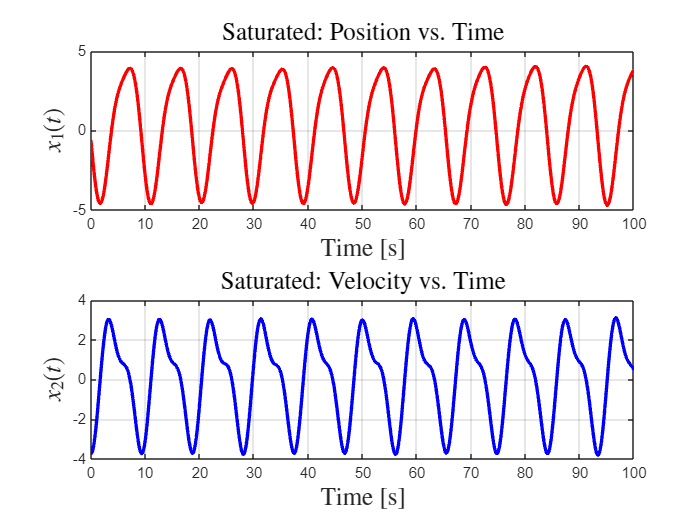

% Parameters
K = 1;            % Proportional gain
umax = 1;         % Maximum allowable control input (saturation limit)

% System matrices
A = [-0.05, 1; -10, -0.5];
B = [0; 1];
C = [9.9, 0.495];

A = [0, 1; -1,0];
B = [1; 0];
C = [1,1];

m1 = 0.9; m2 = 1.1; K = 10; beta = 0.03;
a0 = (m1^2+beta^2)*(m2^2+beta^2); a1 = 2*beta*(m1^2+m2^2+2*beta^2); a2 = m1^2+m2^2+6*beta^2; a3 = 4*beta;
A = [ 0 1 0 0 ; 0 0 1 0; 0 0 0 1; -a0,-a1,-a2,-a3];
B = [0 ;0 ;0;1];
C =[0 0 -1 0];

% Define the system of ODEs with input saturation
systemWithSaturation = @(t, x) A*x + B*saturateInput(C*x, umax);
systemWithoutSaturation = @(t, x) A*x + B*K*C*x;

% Initial conditions
x0 = [-0.6252; -3.732;0; 3.4754];  % Initial position and velocity

% Time span
tspan = [0 100];  % Simulate from t=0 to t=10

% Solve the system using ode45
[t, x] = ode45(systemWithSaturation, tspan, x0);
[t2, x2] = ode45(systemWithoutSaturation, tspan, x0);

% Plot the results
 figure;
subplot(2,1,1);
plot(t, x(:, 1), 'r', 'LineWidth', 2);
xlabel('Time [s]','interpreter','latex','fontsize',15);
ylabel('$x_1(t)$','interpreter','latex','fontsize',15);
title('Saturated: Position vs. Time','interpreter','latex','fontsize',15);
grid on;

subplot(2,1,2);
plot(t, x(:, 2), 'b', 'LineWidth', 2);
xlabel('Time [s]','interpreter','latex','fontsize',15);
ylabel('$x_2(t)$','interpreter','latex','fontsize',15);
title('Saturated: Velocity vs. Time','interpreter','latex','fontsize',15);
grid on;

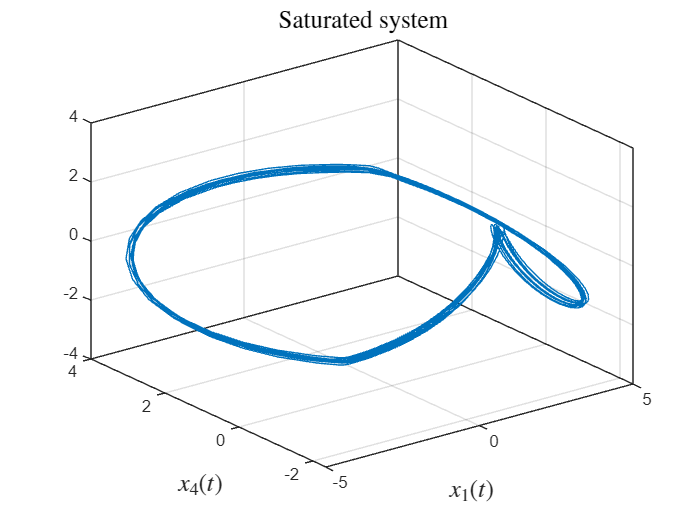


 figure;
plot3(x(:, 1),x(:, 3),x(:, 4))
xlabel('$x_1(t)$','interpreter','latex','fontsize',15);
ylabel('$x_3(t)$','interpreter','latex','fontsize',15);
ylabel('$x_4(t)$','interpreter','latex','fontsize',15);
title('Saturated system','interpreter','latex','fontsize',15);
grid on; box;

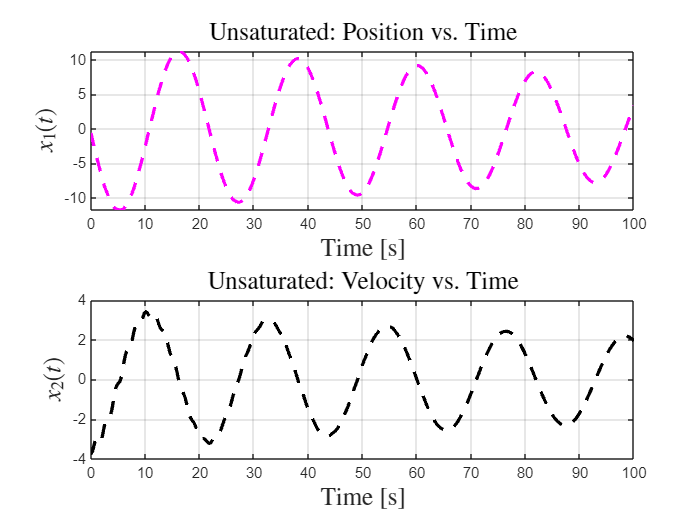



% Plot the results
figure;
subplot(2,1,1);
plot(t2, x2(:, 1), '--m', 'LineWidth', 2);
xlabel('Time [s]','interpreter','latex','fontsize',15);
ylabel('$x_1(t)$','interpreter','latex','fontsize',15);
title('Unsaturated: Position vs. Time','interpreter','latex','fontsize',15);
grid on;

subplot(2,1,2);
plot(t2, x2(:, 2), '--k', 'LineWidth', 2);
xlabel('Time [s]','interpreter','latex','fontsize',15);
ylabel('$x_2(t)$','interpreter','latex','fontsize',15);
title('Unsaturated: Velocity vs. Time','interpreter','latex','fontsize',15);
grid on;

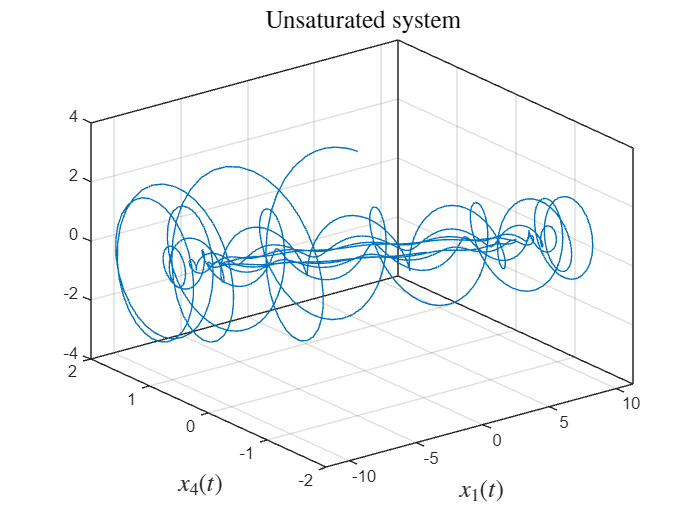


figure;
plot3(x2(:, 1),x2(:, 3),x2(:, 4))
xlabel('$x_1(t)$','interpreter','latex','fontsize',15);
ylabel('$x_3(t)$','interpreter','latex','fontsize',15);
ylabel('$x_4(t)$','interpreter','latex','fontsize',15);
title('Unsaturated system','interpreter','latex','fontsize',15);
grid on; box

### 6.2 Equilibrium points

Another peculiarity of nonlinear systems is that they can have multiple equilibrium points. Recall from the code "***stability_analysis_control101_tool.mlx***" that an equilibrium point of a system is defined as:

**Definition**: A equilibrium point $x_e$ of a nonlinear system, $\frac{dx(t)}{dt} = F(x(t))$, satisfies $F(x_e) = 0$.

What this definition implies is that if $x(t)= x_e$, then the state will not move since ${dx(t)}/{dt} = 0$. Equilibrium points are essential concepts in stability analysis, and it is around these points that the stability concepts for nonlinear systems will be defined. 

One of the main challenges faced when analysing nonlinear systems is that they can have multiple equilibrium points. To see this, consider the dynamics:

$\frac{dx(t)}{dt} = (1-x(t))\times (1+x(t))$.

Here, $F(x(t)) = (1-x(t))\times (1+x(t))$. Notice that there are two points where $F(x_e) = 0$ correpsonding to the two roots of this quadratic polynomial, as in $x_e = 1$ and $x_e = -1$, as plotted below.

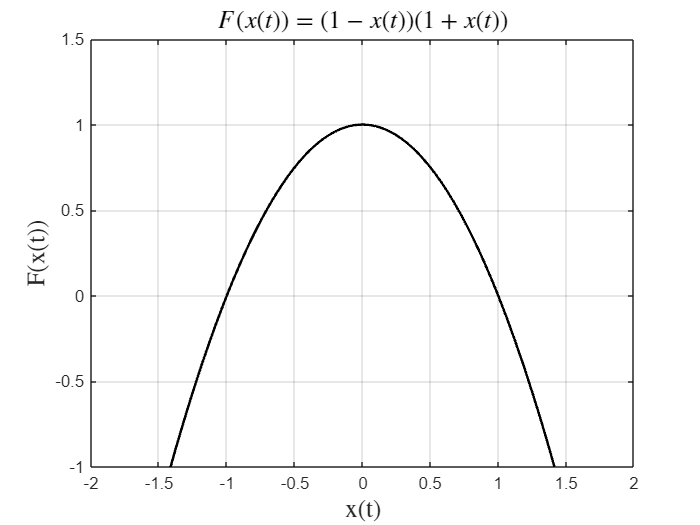


% Define the range for x
x = linspace(-2, 2, 1000);  % Create 1000 points between -2 and 2

% Compute the function values for each x
y = (1-x).*(1+x);

% Plot the function
figure;
plot(x, y, '-k','LineWidth', 1.5);
grid on;

% Add labels and title
xlabel('x(t)','interpreter','latex','fontsize',15);
ylabel('F(x(t))','interpreter','latex','fontsize',15);
title('$F(x(t)) = (1 - x(t))(1 + x(t))$','interpreter','latex','fontsize',15);

% Customize plot
xlim([-2 2]);  % Set x-axis limits
ylim([-1 1.5]);  % Set y-axis limits based on the function's range

Equilibrium points are places in the state-space where our dynamics remain indefinitely. This key property will be used to justify defining our stability analysis locally around these points. But, we have to be clear as to what equilibrium point our analysis is applied to, because each point may have different characteristics. 

### 6.3 Linearisation of nonlinear systems

Our goal is to adapt the techniques we have develloped for the stability analysis of linear time invariant systems to nonlinear systems. For this, we will consider **linearising** the system dynamics. What this means is that we will approximate the nonlinear dynamics, $F(x(t))$, around the equilibrium point, $x_e$, using a first-order Taylor approimation at that point:


$$F(x(t)) = F(x_e)+ \left.\frac{dF(x(t))}{dx(t)}\right|_{x(t) = x_e}(x(t)-x_e) + \mathcal{O}(x(t)-x_e)^2 \qquad \qquad \qquad \text{Eqn. (3)}$$


where $\mathcal{O}(x(t)-x_e)^2$ means the error of the approximation of the above decays/grows at a rate proportional to the square of $(x(t)-x_e)$. We will define a linear approximation of the function $F$ by taking the first two terms in this Taylor expansion.

**Definition:** The linearisation of a nonlinear vector field is defined as the first two terms of the Taylor-expansion. Specifically, the linearised vector field is defined by:


$$F(x(t)) \approx F(x_e)+ \left.\frac{dF(x(t))}{dx(t)}\right|_{x(t) = x_e}(x(t)-x_e) 
$$


We refer to the term $\left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}$ as the Jacobian of $F$ evaluated at the point $x_e$. This is approximation is also known as a "*first-order approximation*" of the vector field $F$. 

**Definition:** Consider a vector field $F$ and state $x(t)$ defined as vectors


$$F(x(t)) = \left[\matrix{F_1(x(t)) \cr F_2(x(t)) \cr \vdots \cr F_n(x(t))}\right], \qquad x(t) = \left[\matrix{x_1(t) \cr x_2(t) \cr \vdots \cr x_n(t)}\right].$$


The Jacobian of a vector field $F$, defined as $\left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}$, is calculated by taking derivatives of each term in $F$ with respect to the states, as in

$\left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}
 = \left.\left[\matrix{\frac{d\,F_1(x)}{dx_1(t)} & {\frac{d\,F_1(x)}{dx_2(t)}  & \dots & {\frac{d\,F_1(x)}{dx_n(t)} \cr 
{\frac{d\,F_2(x)}{dx_1(t)}  & {\frac{d\,F_2(x)}{dx_2(t)}   & \ddots & \vdots
\cr
\left.\vdots & \ddots& \ddots &{\frac{d\,F_{n-1}(x)}{dx_n(t)}  
\cr {\frac{d\,F_n(x)}{dx_1(t)}    & \dots & {\frac{d\,F_n(x)}{dx_{n-1}(t)} & {\frac{d\,F_n(x)}{dx_n(t)}}  }\right]
\right|_{x(t) = x_e}
$.

Notice that if the dimension of the states-space is $n$, as in $x(t) \in \mathbb{R}^n$, then the Jacobian of $F$ is a $n \times n$ matrix whose elements are formed from taking the derivatives of the vector field with respect to the states and then evaluating at the specific equilibrium point, $x_e$, of interest to the analysis. 

From Eqn. (3) above, we can infer that if the state $x(t)$ is close to the equilibrium point, $x_e$, then the first-order approximation of the vector field (defined by the Jacobian matrix) will be quite good. Specifically, the Taylor expansion implies the error of the first-order approximation will decrease as the square of $(
x(t)-x_e)$ due to the $\mathcal{O}(x(t)-x_e)^2$term. So, if $(x(t)-x_e) <1$, then $(x(t)-x_e)^2 \ll1$(using the notation that $x \ll y$ impllies $x
$ is **much** smaller than $y$). 

So, if our state is close to the equilibrium point, then our first-order approximation is quite good. However, if we are far away (as in $(x(t)-x_e) \gg 1$) then our approximation is likely to be bad since then $(x(t)-x_e)^2 \gg1$. This is why our first linearised approxiamtion is also said to be a **local approximation**: it performs well only when our state $x(t)$ is locally close to the equilibrium, and it often is a poor approximation when far away. 

### 6.4 Variational dynamics

The value of the Jacobian for the stability analysis of nonlinear systems is that it allows us to define a set of dynamics for the error between the state and the equilibrium point which are valid locally around the point. Specifically, define the variational state $\tilde{x}(t) = x(t)-x_e$ as the difference between the state $x(t)$ and the equilibrium point $x_e$. Our goal is now to analyse the stability of these variational states and so infer whether the states will *blow up *relative to the point $x_e$ or not. This is the key difference between the stability analysis of linear and nonlinear systems. For nonlinear systems, we are concerned with the growth of the states relative $x_e$, and everything is done relative to these points. 

In particular, we can write some dynamics for these variational states by:

$\frac{d\,\tilde{x}(t)}{dt}
=
\frac{d\,(x(t)-x_e)}{dt}
=
F(x(t)) \approx \underbrace{F(x_e)}_{ = 0}+ \left.\frac{dF(x(t))}{dx(t)}\right|_{x(t) = x_e}(x(t)-x_e) 
=
\left.\frac{dF(x(t))}{dx(t)}\right|_{x(t) = x_e}\tilde{x}(t) $.

This equation implies that we can use the linearisation to get a linear time-invariant system of the form of Eqn (1):


$$\frac{d\,\tilde{x}(t)}{dt} = A\tilde{x}(t)$$


with an $A$ matrix defined by:


$$A= \left.\frac{dF(x(t))}{dx(t)}\right|_{x(t) = x_e}.$$


Therefore, we can define a linear time invariant system that approximates the nonlinear one locally around an equilibrium point.  The $A$ matrix of this linear approximation is defined by the Jacobian of the vector field. With this approximation, we can then apply the methods to analyse the stability of LTI systems (by checking the eigenvalues of $A$) to nonlinear systems. 

### Examples

For example, consider the vector field of the Van der Pol oscillator again with: 

$F(x(t)) =
\left[\matrix{x_2(t)  \cr \mu(1-x_1(t)^2)\times x_2(t)-x_1(t)} \right]


$.

 Notice that the origin is an equilibrium point of this system. In other words, when $x_e = 0$ then:

$F(x_e) =
\left[\matrix{x_{e,2}  \cr \mu(1-x_{e,1}^2)x_{e,1}-x_{e,1}} \right]
=
\left[\matrix{0  \cr \mu(1-0^2)\times 0-0} \right] =  \left[\matrix{0  \cr 0} \right]$.

To compute the linearisation of this vector field around this point, we compute the Jacobian:


$$\left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}
= \left. \left[\matrix{\frac{dF_1(x)}{d x_1}  & \frac{dF_1(x)}{d x_2} \cr \frac{dF_2(x)}{d x_1} & \frac{dF_2(x)}{d x_2}}\right] \right|_{x(t) = x_e}
=
 \left.\left[\matrix{\frac{dx_2}{d x_1}  & \frac{dx_2}{d x_2} \cr \frac{d(\mu(1-x_1(t)^2)\times x_2(t)-x_1(t))}{d x_1} & \frac{d(\mu(1-x_1(t)^2)\times x_2(t)-x_1(t))}{d x_2}}\right] \right|_{x(t) = x_e}$$


Taking these derivatives gives and evaluatting at $x_e = 0
$ gives the Jacobian:

$\left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}
=
 \left.\left[\matrix{0  &1 \cr 
-2\mu \times  x_1(t)x_2(t)-1 &  (\mu(1-x_1(t)^2)}\right] \right|_{x(t) = x_e}
=
 \left.\left[\matrix{0  &1 \cr 
-1&  \mu}\right] $.

We can then get our first order Taylor approximation of the Van der Pol Oscillator around the equilibrium point at the origin:


$$F(x(t)) =
\left[\matrix{x_2(t)  \cr \mu(1-x_1(t)^2)\times x_2(t)-x_1(t)} \right]
\approx
 \left[\matrix{0 \cr 0} \right]+  \left.\left[\matrix{0  &1 \cr 
-1&  \mu}\right] (x(t)-x_e) 
=
 \left.\left[\matrix{0  &1 \cr 
-1&  \mu}\right] (x(t)-x_e) 
=
\left[\matrix{x_2(t) \cr 
-(x_1(t))+ \mu(x_2(t) )}\right] $$


The code below compares the accuracy of this first-order approximation of the Van der Pol oscilator by linearising the dynamics at the origin.  Notice that the linear approximation of the model is quite good around the origin (both plots show the states curling away). But, as time goes and the states get further and further away from the origin, the linear approximation gets worse and worse. By the end, the linear approximation becomes unstable and keeps on getting bigger whilst the nonlinear system enters into a limit cycle and so remains bounded. 

% Parameters
mu = 1;  % Van der Pol oscillator parameter (nonlinearity)

% Time span for the simulation
tspan = [0 20];

% Initial conditions (same for both systems)
x0 = [0.01; 0.01];  % Start with an initial displacement from equilibrium

% Van der Pol oscillator (nonlinear system)
vanDerPol = @(t, x) [x(2);
                     mu*(1 - x(1)^2)*x(2) - x(1)];

% Linearized system around the origin (linear approximation)
linearisedSystem = @(t, x) [x(2);
                            -x(1)+mu*x(2)];

A = [0 1; -1 mu];

% Check the stability of the eigenvalues
disp('The eigenvalues of A are:');disp(eig(A));

The eigenvalues of A are:
   0.5000 + 0.8660i
   0.5000 - 0.8660i



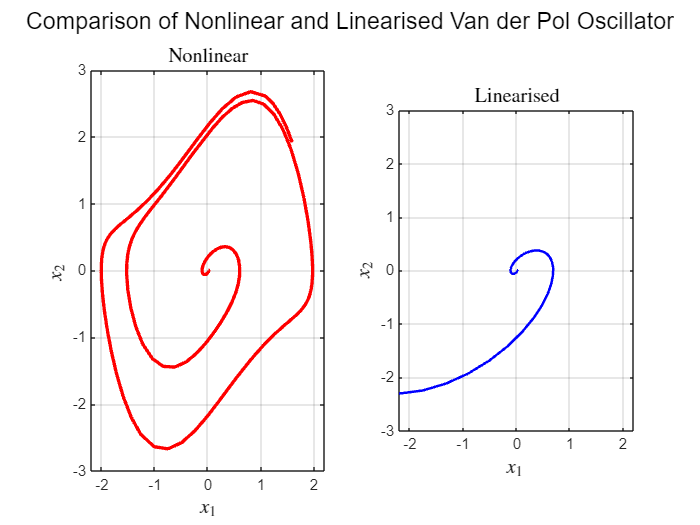


% Solve the nonlinear Van der Pol oscillator
[t_nonlinear, x_nonlinear] = ode45(vanDerPol, tspan, x0);

% Solve the linearized system
[t_linear, x_linear] = ode45(linearisedSystem, tspan, x0);

% Plot comparison in the phase portrait
figure;

% Nonlinear Van der Pol oscillator plot
subplot(1, 2, 1);
plot(x_nonlinear(:, 1), x_nonlinear(:, 2), 'r', 'LineWidth', 2);
xlabel('$x_1$','interpreter','latex','fontsize',12);
ylabel('$x_2$ ','interpreter','latex','fontsize',12);
title('Nonlinear','interpreter','latex','fontsize',12);
grid on;
axis([-2.2 2.2 -3 3]);

% Linearized system plot
subplot(1, 2, 2);
plot(x_linear(:, 1), x_linear(:, 2), 'b', 'LineWidth', 1.5);
xlabel('$x_1$ ','interpreter','latex','fontsize',12);
ylabel('$x_2$','interpreter','latex','fontsize',12);
title('Linearised','interpreter','latex','fontsize',12);
grid on;
axis equal;
axis([-2.2 2.2 -3 3]);

% Overall plot settings
sgtitle('Comparison of Nonlinear and Linearised Van der Pol Oscillator');

### 6.5 Local asympotic stability of nonlinear systems

Using the linearised approximation of the nonliner dynamics described in the text above, we now have a method to test the local stability of a nonlinear system around an equilibrium point. We say that the stability conditions are local because they are only valid in the region where the linearisation gives a good approximation of the vector field $F(x(t))$. When the states are far away from the equilibrium point, we can not say anything about the stability. In that case, if we want to asses the global stability, as in the system is stable everywhere no matter how close we are to the equilibrium point, then we have to use fancier tools such as Lyapunov functions [*Åström, Karl Johan, and Richard Murray. Feedback systems: an introduction for scientists and engineers. Princeton university press, 2021*].

Using this analysis, we then apply the following procedure to determine the local stability of nonlinear systems:

- Linearise the nonlinear dynamics $F(x(t))  \approx F(x_e)+ \left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}(x(t)-x_e) $.

- Write down the linear approximation for the variation of the states around this equilibrium point $\tilde{x}(t) = x(t)-x_e$.

- State dynamics for the variational states $\frac{d\tilde{x}(t)}{dt} = A\tilde{x}(t)$ where $A = \left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = x_e}$ is defined from the Jacobian of the vector field. 

- Calculate the eigenvalues of the Jacobian matrix $A$.

- If the real part of the eigenvalues of $A$ are strictly positive, then the system is locally asympotically unstable.

- If the real part of the eigenvalues of $A$ are strictly negative, then the system is locally asympotically stable.

- If the real part of the eigenvalues of $A$ equal zero , then the system is locally neutrally stable.

#### Example 1: Unstable linear system

For example, if we take the Van der Pol oscillator once more from the above code, we have that:


$$A = \left.\frac{dF(x(t)}{dx(t))}\right|_{x(t) = x_e}
=
 \left.\left[\matrix{0  &1 \cr 
-2\mu \times  x_1(t)x_2(t)-1 &  \mu(1-x_1(t)^2)}\right] \right|_{x(t) =0}
=
 \left.\left[\matrix{0  &1 \cr 
-1&  \mu}\right] ,$$


whose eigenvalues are:


$$\text{det}(\lambda I_2-A) = 
\text{det}\left(\lambda \left.\left[\matrix{1  &0 \cr 
0&  1}\right] 
-\left.\left[\matrix{0  &1 \cr 
-1&  \mu}\right] \right) 
=
\text{det}\left(\left.\left[\matrix{\lambda  &-1 \cr 
1& \lambda- \mu}\right] \right) 
=
\lambda \times (\lambda-\mu)+1 = 0$$


with solution:


$$\lambda_1 = \frac{1}{2}\left(\mu-\sqrt{\mu^2-4}\right), \quad \lambda_2= \frac{1}{2}\left(\mu+\sqrt{\mu^2-4}\right).$$


Since $\mu = 1$, these eigenvalues have a positive real paer and so we can infer that the system is locally unstable around the origin. This is the reason why the trajectories move away from the origin before eventually converging towards a limit cycle. 

#### Example 2: Stable linear system

Consider instead the system defined by:

$
\frac{d\,x(t)}{dt}
=
\frac{d\,}{dt}  \left.\left[\matrix{x_1(t) \cr 
x_2(t)}\right]
=
F(x(t)) =  \left.\left[\matrix{F_1(x(t)) \cr 
F_2(x(t))}\right] =   \left.\left[\matrix{x_2(t) \cr 
-2\sin(3x_1(t) - 5x_2(t)(1-{x_1}^2)}\right]$.

Notice that the origin is an equilibrium point of this system,


$$ \left.\left[\matrix{0 \cr 
2\sin(0) + 5\times 0\times 1}\right] =   \left.\left[\matrix{0 \cr 
0}\right].$$


Therefore, take $x_e = 0$. The linearised dynamics around this equilibrium point are defined by


$$\frac{d\tilde{x}(t)}{dt} = A\tilde{x}(t) \qquad \text{where } A = \left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = 0}.$$


Calculating the Jacobian, we have that: 

$A = \left.\frac{dF(x(t))}{dx(t))}\right|_{x(t) = 0}
=
 \left.\left[\matrix{\frac{d F_1(x(t))}{d x_1(t)} &\frac{d F_1(x(t))}{d x_2(t)} \cr 
\frac{d F_2(x(t))}{d x_1(t)}  & \frac{d F_2(x(t))}{d x_2(t)} }\right] \right|_{x(t) = 0}
=
 \left.\left[\matrix{0  &1 \cr 
-6\cos(3x_1(t))+ 10x_1x_2 &  -5(1-{x_2(t)}^2)}\right] \right|_{x(t) = 0}
=
\left[\matrix{0  &1 \cr 
-6\cos(0)+ 10\times 0 \times 0 &  -5(1-{0}^2)}\right] 
=
\left[\matrix{0  &1 \cr 
-6 &  -5}\right] $Computing the eigenvalues of $A$ gives:


$$\text{det}(\lambda I_2-A) = 
\text{det}\left(\lambda \left.\left[\matrix{1  &0 \cr 
0&  1}\right] 
-\left.\left[\matrix{0  &1 \cr 
-6 &  -5}\right]  \right) 
=
\text{det}\left(\left.\left[\matrix{\lambda  &-1 \cr 
6& \lambda+5}\right] \right) 
=
\lambda \times (\lambda+5)+6
= (\lambda+3)(\lambda+2) \times = 0.$$


Therefore, the eigenvalues of this system are at $\lambda_1 = -3$ and $\lambda_2 = -2$. As these eigenvalues have negative real-parts, the system is asympotically stable locally around the equilibrium point. The following code verifies this. 

% Time span for the simulation
tspan = [0 20];

% Initial conditions (same for both systems)
x0 = [pi/6;1.1];  % Start with an initial displacement from equilibrium

% Nonlinear system dynamics
NonlienarDynamics = @(t, x) [x(2);
                     -2*sin(3*x(1))-5*x(2)*(1-x(1)^2)];

% Linearized system around the origin (linear approximation)
linearisedSystem = @(t, x) [x(2);
                            -6*x(1)-5*x(2)];

A = [0 1; -6 -5];

% Check the stability of the eigenvalues
disp('The eigenvalues of A are:');disp(eig(A));

The eigenvalues of A are:
   -2.0000
   -3.0000



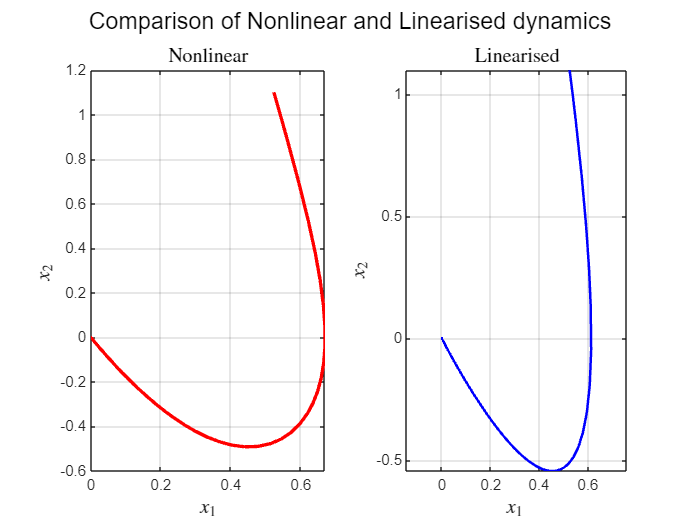


% Solve the nonlinear Van der Pol oscillator
[t_nonlinear, x_nonlinear] = ode45(NonlienarDynamics, tspan, x0);

% Solve the linearized system
[t_linear, x_linear] = ode45(linearisedSystem, tspan, x0);


% Plot comparison in the phase portrait
figure;

% Nonlinear dynamics plot
subplot(1, 2, 1);
plot(x_nonlinear(:, 1), x_nonlinear(:, 2), 'r', 'LineWidth', 2);
xlabel('$x_1$','interpreter','latex','fontsize',12);
ylabel('$x_2$ ','interpreter','latex','fontsize',12);
title('Nonlinear','interpreter','latex','fontsize',12);
grid on;
% axis([-2.2 2.2 -3 3]);

% Linearised system plot
subplot(1, 2, 2);
plot(x_linear(:, 1), x_linear(:, 2), 'b', 'LineWidth', 1.5);
xlabel('$x_1$ ','interpreter','latex','fontsize',12);
ylabel('$x_2$','interpreter','latex','fontsize',12);
title('Linearised','interpreter','latex','fontsize',12);
grid on;
axis equal;
% axis([-2.2 2.2 -3 3]);

% Overall plot settings
sgtitle('Comparison of Nonlinear and Linearised dynamics');

## 7. Conclusions 

In this code, we explored how to analyse the stability of dynamical systems. We began by discussing eigenvalues and eigenvectors of matrices before showing how they could be used to determine the stability of linear-time invariant systems. We then generalised the analysis to look at nonlinear systems and explored how to study the stability of those systems locally around equilibrium points.  

## Functions

% Function to apply input saturation

function u_sat = saturateInput(u, umax)
N = 0.05;
    u_sat = max(min(u, umax), -umax);
    if u <= -N
        u_sat = -1;
    elseif -N<=u  && u<=N
        u_sat = u/N;
            elseif u>=N
        u_sat = 1;
    end

end
